# Convolutional Code in AWGN

*Version 15.7.2025*

## Rate 1/2 Convolutional Code in AWGN

This example generates a bit error rate versus $E_b /N_0$ curve for a link that uses 16-QAM modulation and a rate 1/2 convolutional code in AWGN.

Set the modulation order, and compute the number of bits per symbol.

clear
M = 16;
k = log2(M);

Create a trellis for a rate 1/2 convolutional code. The constraint length is set to 8. Set the traceback and code rate parameters accordingly.

trellis = poly2trellis(8,[333 253]);
traceBack = 40;
codeRate = 1/2;

Create a convolutional encoder and its equivalent Viterbi decoder to run in the continuous mode.

convEncoder = comm.ConvolutionalEncoder(TrellisStructure=trellis);
vitDecoder = comm.ViterbiDecoder( ...
    TrellisStructure=trellis, ...
    InputFormat='Hard', ...
    TracebackDepth=traceBack);

Create an error rate object. Set the receiver delay to be equal to the traceback depth, which is the delay through the decoder.

errorRate = comm.ErrorRate(ReceiveDelay=traceBack);

Set the range of $E_b /N_0$ values to be simulated and compute the equivalent SNR values. Initialize the bit error rate statistics matrix.

ebnoVec = 0:2:10;
snr = convertSNR(ebnoVec,"ebno","snr", ...
    BitsPerSymbol=k, ...
    CodingRate=codeRate);
errorStats = zeros(length(ebnoVec),3);

Simulate the link by following these steps:

- Generate binary data.

- Encode the data with a rate 1/2 convolutional code.

- 16-QAM modulate the encoded data, configure bit inputs and unit average power.

- Pass the signal through an AWGN channel.

- 16-QAM demodulate the received signal configure bit outputs and unit average power.

- Decode the demodulated signal by using a Viterbi decoder.

- Collect the error statistics.

for ii = 1:length(ebnoVec)
    while errorStats(ii,2) <= 100 && errorStats(ii,3) <= 2e7
        dataIn = randi([0 1],12000,1);
        dataEnc = convEncoder(dataIn);
        txSig = qammod(dataEnc,M, ...
            InputType='bit',UnitAveragePower=true);
        rxSig = awgn(txSig,snr(ii),'measured');
        demodSig = qamdemod(rxSig,M, ...
            OutputType='bit',UnitAveragePower=true);
        dataOut = vitDecoder(demodSig);
        errorStats(ii,:) = errorRate(dataIn,dataOut);
    end
    reset(errorRate)
end

Compute the theoretical BER curve for the case without forward error correction coding by using the [`berawgn`](docid:comm_ref#fp1562672) function.

berUncoded_emp = berawgn(ebnoVec','qam',M);

Compute the theoretical BER curve for the case with forward error correction coding by using the [`bercoding`](docid:comm_ref#fp1588513) function and the distance spectrum for the 1/2 rate convolutional code. The [`distspec`](docid:comm_ref#a1053376622b1) function computes the distance spectrum of convolutional codes and outputs the distance spectrum structure.

spect = distspec(trellis,6);
berCoded_emp = bercoding(ebnoVec', ...
    'conv','hard',codeRate,spect,'qam',M);

Plot BER versus $E_b /N_0$ curves for the simulated coded data, and the theoretical uncoded and coded data.

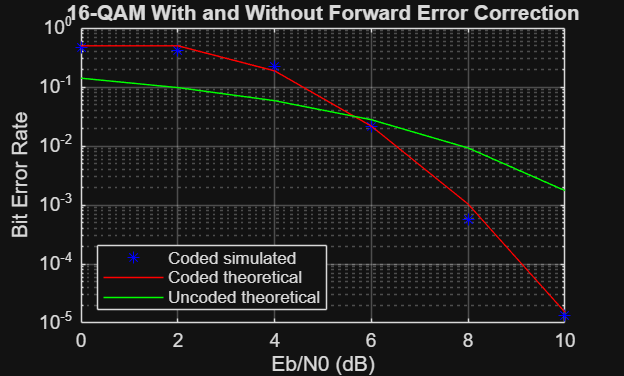

semilogy(ebnoVec,errorStats(:,1),'b*', ...
    ebnoVec,berCoded_emp,'r-', ...
    ebnoVec,berUncoded_emp,'g')
grid
legend('Coded simulated','Coded theoretical','Uncoded theoretical', ...
     'Location','southwest')
title('16-QAM With and Without Forward Error Correction')
xlabel('Eb/N0 (dB)')
ylabel('Bit Error Rate')

## Effects of Constraint Length

In this section, the simulation is repeated with a shorter constraint length.

Create a trellis for a rate 1/2 convolutional code. The constraint length is now set to 4. The traceback parameter is set accordingly.

trellisCL4 = poly2trellis(4,[17 15]);
traceBackCL4 = 20;

Create a convolutional encoder and its equivalent Viterbi decoder to run in the continuous mode.

convEncoderCL4 = comm.ConvolutionalEncoder(TrellisStructure=trellisCL4);
vitDecoderCL4 = comm.ViterbiDecoder( ...
    TrellisStructure=trellisCL4, ...
    InputFormat='Hard', ...
    TracebackDepth=traceBackCL4);

Create an error rate object. Set the receiver delay to be equal to the traceback depth, which is the delay through the decoder.

errorRateCL4 = comm.ErrorRate(ReceiveDelay=traceBackCL4);

Initialize the bit error rate statistics matrix.

errorStatsCL4 = zeros(length(ebnoVec),3);

Simulate the link.

for ii = 1:length(ebnoVec)
    while errorStatsCL4(ii,2) <= 100 && errorStatsCL4(ii,3) <= 1e7
        dataIn = randi([0 1],12000,1);
        dataEncCL4 = convEncoderCL4(dataIn);
        txSigCL4 = qammod(dataEncCL4,M, ...
            InputType='bit',UnitAveragePower=true);
        rxSigCL4 = awgn(txSigCL4,snr(ii),'measured');
        demodSigCL4 = qamdemod(rxSigCL4,M, ...
            OutputType='bit',UnitAveragePower=true);
        dataOutCL4 = vitDecoderCL4(demodSigCL4);
        errorStatsCL4(ii,:) = errorRateCL4(dataIn,dataOutCL4);
    end
    reset(errorRateCL4)
end

Plot BER versus $E_b /N_0$ curves for the simulated coded data with both constraint lengths, and the theoretical uncoded data.

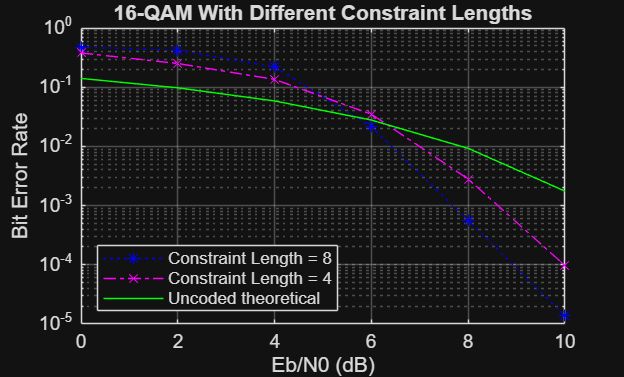

semilogy(ebnoVec,errorStats(:,1),':b*', ...
    ebnoVec,errorStatsCL4(:,1),'-.mx', ...
    ebnoVec,berUncoded_emp,'g')
grid
legend('Constraint Length = 8','Constraint Length = 4','Uncoded theoretical', ...
     'Location','southwest')
title('16-QAM With Different Constraint Lengths')
xlabel('Eb/N0 (dB)')
ylabel('Bit Error Rate')

*Copyright 2012-2023 The MathWorks, Inc.*